# FLIm DEMO

## Select root folders

root = uigetdir; % example SS 2023: C:\Users\Alba Alfonso Garcia\Box\NCIBT_SummerSchool\Demo
disp(['User selected: ', root]); % path to main folder for codes and data

User selected: C:\Users\Alba Alfonso Garcia\Box\NCIBT_SummerSchool\Demo


dataFolderName = 'NCIBT_SS_Demo20230710'; % subpath to data - should be within "root"

## Tabulate FLIm data with labels

Determine the root folder, file with labels, save names

name of the excel file with the scan-labels key (ex. SS demo 2023: 20230710_notes.xlsx)

% Open a file selection dialog box
[labelNotesFile, path] = uigetfile('*.xlsx');

% Check if the user clicked Cancel or closed the dialog box
if isequal(labelNotesFile, 0)
   disp('User selected Cancel or closed the dialog box.');
else
   % Display the selected file name and path
   disp(['User selected ', fullfile(path, labelNotesFile)]);
end

User selected C:\Users\Alba Alfonso Garcia\Box\NCIBT_SummerSchool\Demo\NCIBT_SS_Demo20230710\20230710_notes.xlsx



saveFLImTable = ['rawT_' date '_labels.mat'];

Run the tabulation code

Now processing test2_10.mat


runNum = '10'

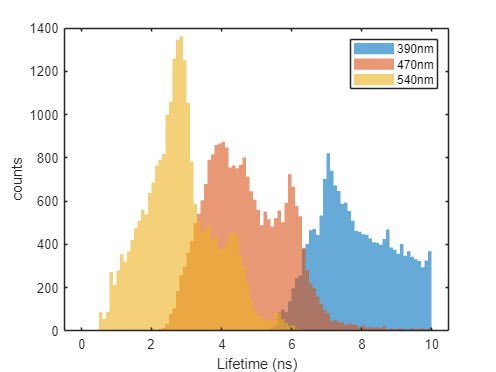

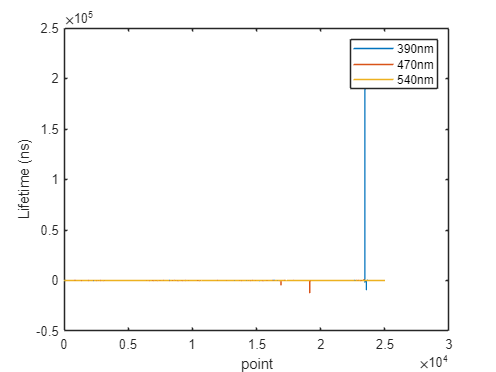

Now processing test2_12.mat


runNum = '12'

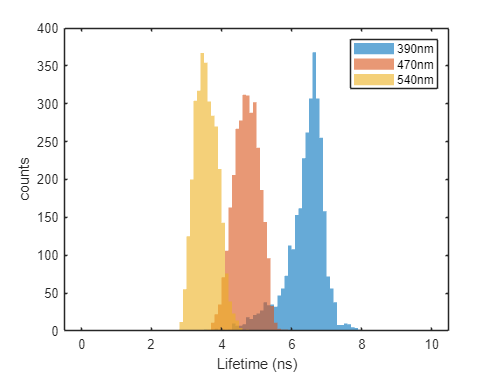

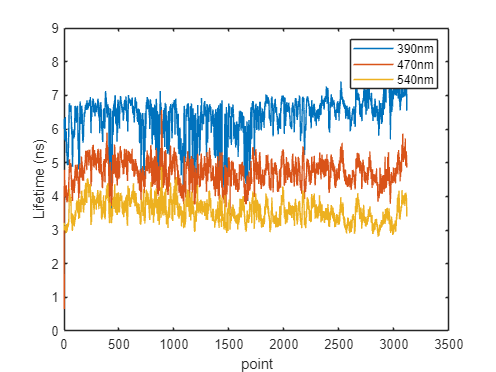

Now processing test2_15.mat


runNum = '15'

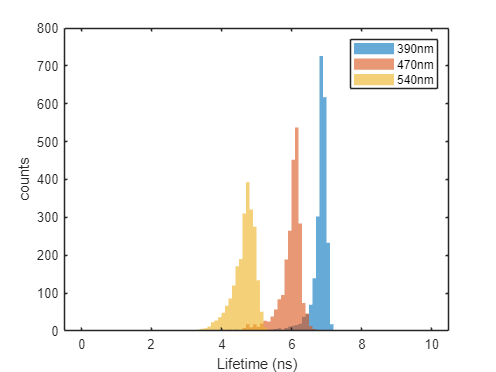

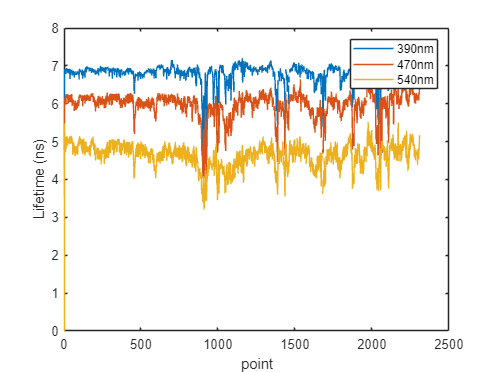

Now processing test2_16.mat


runNum = '16'

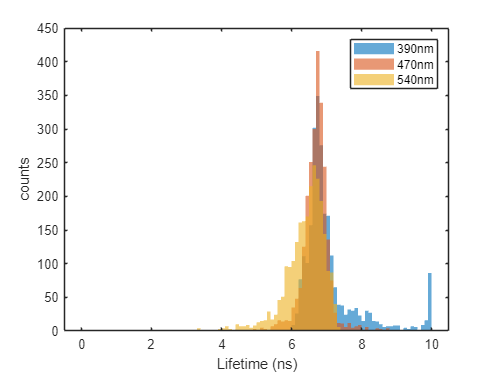

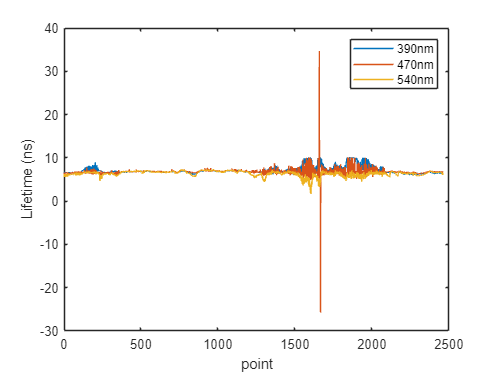

Now processing test2_17.mat


runNum = '17'

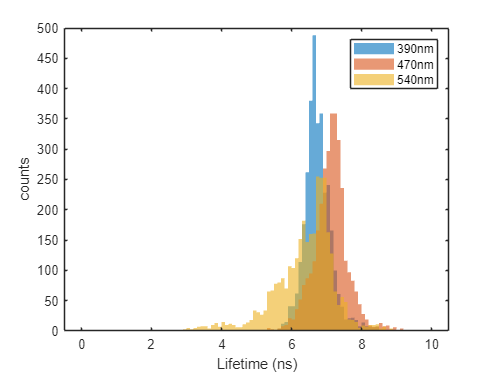

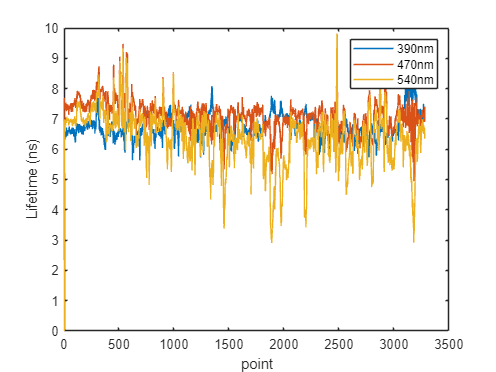

Now processing test2_18.mat


runNum = '18'

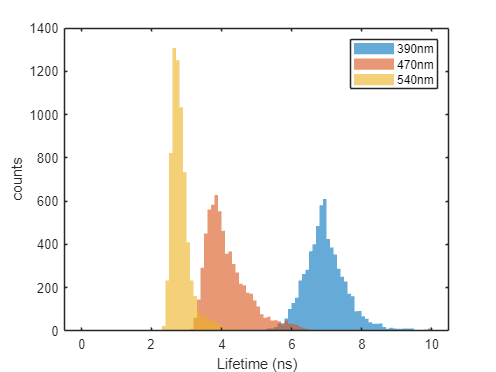

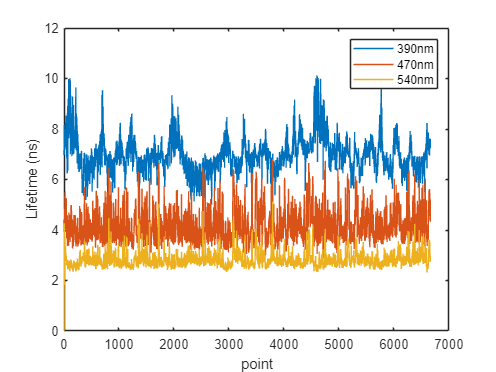

Now processing test2_19.mat


runNum = '19'

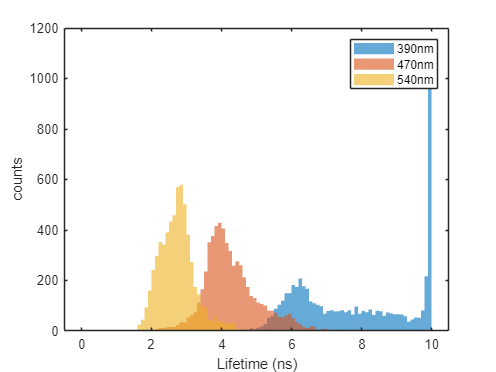

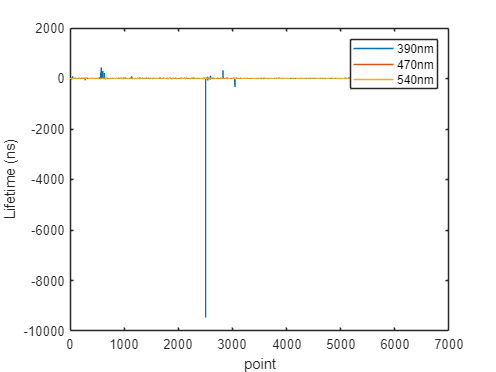

Now processing test2_20.mat


runNum = '20'

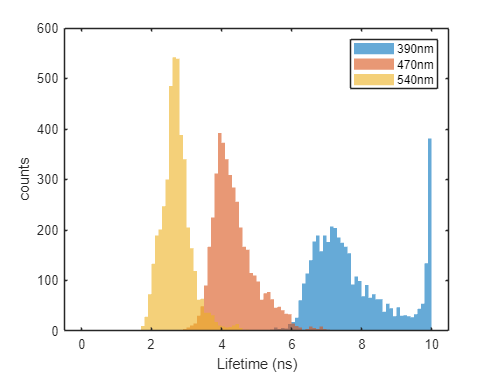

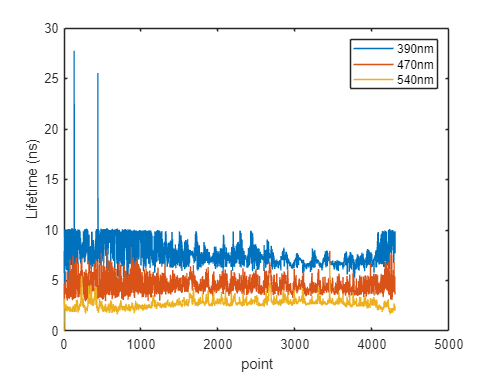

Now processing test2_22.mat


runNum = '22'

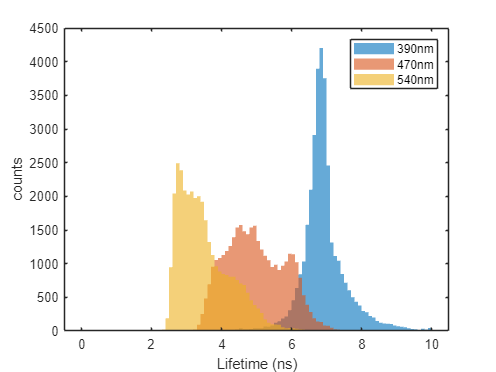

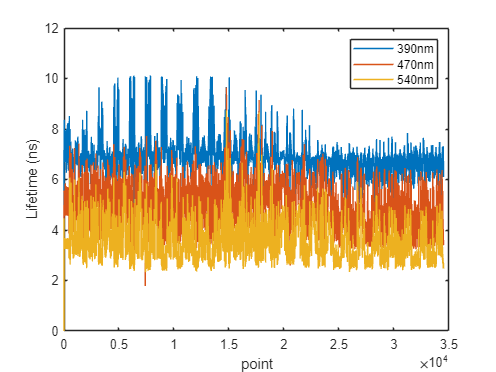

Now processing test2_23.mat


runNum = '23'

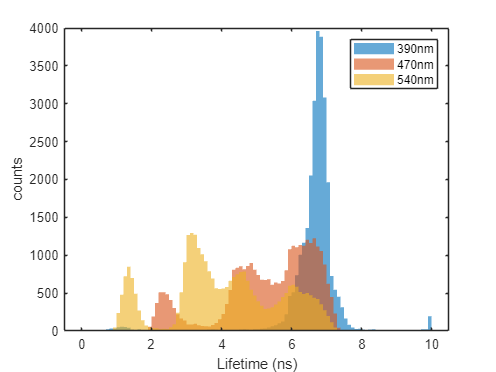

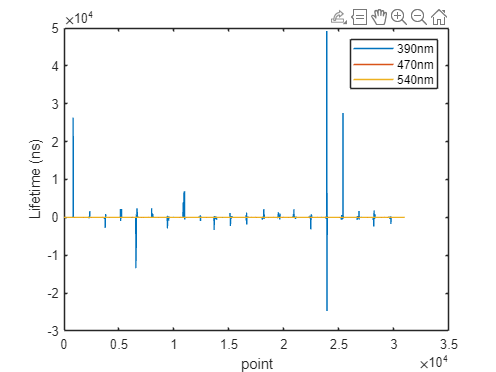

cd([root '\code'])
run tabulateFLIm.mlx;

## Get predefined positions

select root folder

root = uigetdir; % example SS 2023: C:\Users\Alba Alfonso Garcia\Box\NCIBT_SummerSchool\Demo
disp(['User selected: ', root]); % path to main folder for codes and data
dataFolderName = 'NCIBT_SS_Demo20230710' % subpath to data - should be within "root"

Extract positions detected during measurements from the text files in the txt folder

and save them in an independent matlab matrix

cd([root '\' dataFolderName '\txt']);
files = dir('*.txt');
runNum0 = numel(files);
P = [];
for i = 1:length(files)
    textFileName = files(i).name;
    fullFileName = fullfile(textFileName);
    fprintf('Now processing %s\n', fullFileName);
    Num = obtainNumbersInStr(fullFileName);
    runNum = Num(end)
    
    data = load(fullFileName, '-ascii');
    pos = data(:,6:7);
   
    save([fullFileName(1:end-4) '_pos.mat'],'pos')
end

Now processing test2_run1.txt


runNum = 1

Now processing test2_run10.txt


runNum = 10

Now processing test2_run11.txt


runNum = 11

Now processing test2_run12.txt


runNum = 12

Now processing test2_run13.txt


runNum = 13

Now processing test2_run14.txt


runNum = 14

Now processing test2_run15.txt


runNum = 15

Now processing test2_run16.txt


runNum = 16

Now processing test2_run17.txt


runNum = 17

Now processing test2_run18.txt


runNum = 18

Now processing test2_run19.txt


runNum = 19

Now processing test2_run2.txt


runNum = 2

Now processing test2_run20.txt


runNum = 20

Now processing test2_run21.txt


runNum = 21

Now processing test2_run22.txt


runNum = 22

Now processing test2_run23.txt


runNum = 23

Now processing test2_run3.txt


runNum = 3

Now processing test2_run4.txt


runNum = 4

Now processing test2_run5.txt


runNum = 5

Now processing test2_run6.txt


runNum = 6

Now processing test2_run7.txt


runNum = 7

Now processing test2_run8.txt


runNum = 8

Now processing test2_run9.txt


runNum = 9

## Aiming Beam segmentation (manual)

root2 = [root '\' dataFolderName];
cd([root2 '\videos']);

User selected: C:\Users\Alba Alfonso Garcia\Box\NCIBT_SummerSchool\Demo


Choose video to segment manually

(ex. SS demo 2023: videoFile = 'test2_run15.avi')

% Open a file selection dialog box

dataFolderName = 'NCIBT_SS_Demo20230710'

[videoFile, path] = uigetfile('*.avi');

% Check if the user clicked Cancel or closed the dialog box
if isequal(labelNotesFile, 0)
   disp('User selected Cancel or closed the dialog box.');
else
   % Display the selected file name and path
   disp(['User selected ', fullfile(path, labelNotesFile)]);
end

Run manual segmentation code. 

A new window will appear. Be ready to click on the center of the blue spot or where you think the blue spot may be (considering the probe location and the trajectory of the aiming beam in past frames).

cd([root '\code'])
run manualABseg.m;

## Image Reconstruction

Select root folder

root = uigetdir; % example SS 2023: C:\Users\Alba Alfonso Garcia\Box\NCIBT_SummerSchool\Demo
disp(['User selected: ', root]); % path to main folder for codes and data
dataFolderName = 'NCIBT_SS_Demo20230710' % subpath to data - should be within "root"

Run image reconstruction code.

Be prepared to select:

- deconvolution file (in Processed folder)

- text file (in txt folder)

- positions file (in txt folder)

- video file (in videos folder)

from the run/scan you want to reconstruct.

% root = [root '\' dataFolderName];
% cd(root);
% run imageRecon.m

User selected C:\Users\Alba Alfonso Garcia\Box\NCIBT_SummerSchool\Demo\NCIBT_SS_Demo20230710\Analysis\20230710_notes.xlsx


The ouput file will be saved in the Analysis folder.

If starting from a previsouly reconstructed file load it, else skip this step.

root = [root '\Analysis'];

% Open a file selection dialog box
[imgReconFile, path] = uigetfile('*.mat');

% Check if the user clicked Cancel or closed the dialog box
if isequal(labelNotesFile, 0)
   disp('User selected Cancel or closed the dialog box.');
else
   % Display the selected file name and path
   disp(['User selected ', fullfile(path, labelNotesFile)]);
end

load(string(imgReconFile))

Rename image reconstruction output variables for ease of use

run renameOutput.m

Create matrix for plotting spectroscopic outputs

- if data acquired with the scanner stage

circularshift = -20; 

M = [circshift(LT1,circularshift) circshift(LT2,circularshift) circshift(LT3,circularshift) ...
    circshift(I1,circularshift) circshift(I2,circularshift) circshift(I3,circularshift)...
    posx posy];

- if data acquired with hand-held probe

M = [LT1 LT2 LT3 I1 I2 I3 posx posy];

save output

cd([root '\Analysis'])
save('FLIm2Plot.mat','M')

### Plot traces of FLIm parameters

Choose settings

lg = length(LT1);
reprate = 460/4;        % laser repetition rate (divided by number of averages)
time = ((1:lg)./reprate)';  % convert points to time scale

scaleLT = [2 8];        % lifetime scale [min max]
scaleINT = [0 10];       % intensity scale [min max]

k = 25;                 % median fileter kernel size

Plot lifetime traces

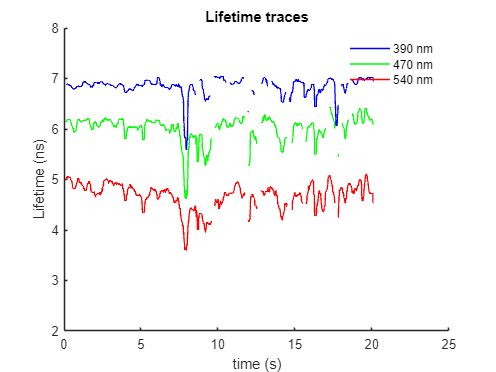

fig1 = figure; 
plot(time,medfilt1(LT1,k),'b','linewidth',1); %hold on; plot(LT,'linewidth',2);
hold on
plot(time,medfilt1(LT2,k),'g','linewidth',1);
plot(time,medfilt1(LT3,k),'r','linewidth',1);
xlabel('time (s)'); ylabel('Lifetime (ns)')
ylim(scaleLT)
box off

legend({'390 nm', '470 nm', '540 nm'})
legend boxoff
title ('Lifetime traces')

Plot intensity traces

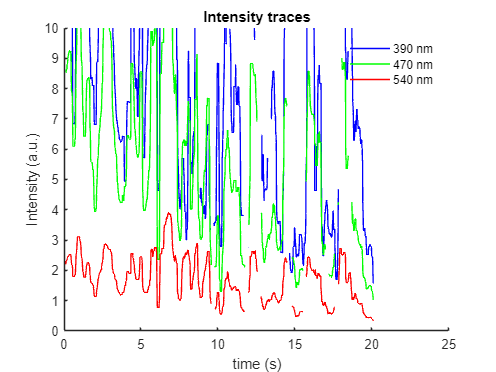

fig2 = figure; 
plot(time,medfilt1(I1,k),'b','linewidth',1); %hold on; plot(LT,'linewidth',2);
hold on
plot(time,medfilt1(I2,k),'g','linewidth',1);
plot(time,medfilt1(I3,k),'r','linewidth',1);
xlabel('time (s)'); ylabel('Intensity (a.u.)')
ylim(scaleINT)
box off
legend({'390 nm', '470 nm', '540 nm'})

legend boxoff
title ('Intensity traces')

### Display overlay

Choose display parameters

displayVar = LT2;       % choose what variable you want to display
displayName = 'Lifetime 470 nm (ns)';
rad = 50;               % overlay disk radius
displayAlpha = 0.1;     % overlay transparency factor
displayScale = scaleLT; % choose what scale to dispaly according to selected variable

Dsiplay

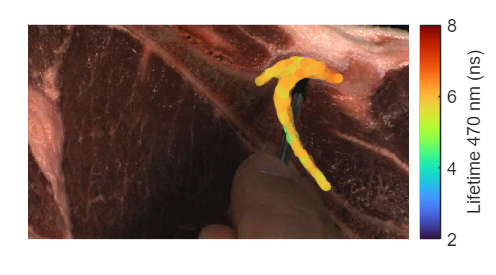

lg = length(posx);          % length vector
r = ones(1,lg)'*rad;        % radius vector
X = displayVar;
circshiftval = -20;     % add shift for scanner-stage images

fig3 = figure; 
imshow(IMG*2); % for dark images : *2
hold on; 
scatter(posx,posy,r,circshift(X,circshiftval),'filled','markerfacealpha',displayAlpha); 
colormap(turbo)

caxis(gca,displayScale);

h0 = colorbar;
h0.Label.String = displayName;

set(gca,'FontSize',15)
set(gca,'LooseInset',get(gca,'TightInset'))